# Comandi per Controllo Robusto

- Dato un sistema definito dalle matrici A,B,C,D

A=[1 3 0;2 4 9;1 1 0];
B=[1 ;2;0 ];
C=[1 0 0];
D=0;
Gss=ss(A,B,C,D)

Gss =
 
  A = 
       x1  x2  x3
   x1   1   3   0
   x2   2   4   9
   x3   1   1   0
 
  B = 
       u1
   x1   1
   x2   2
   x3   0
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



 posso ritrovare la fdt come

s=tf('s');
Gtf=tf(Gss)

Gtf =
 
       s^2 + 2 s - 9
  -----------------------
  s^3 - 5 s^2 - 11 s - 18
 
Continuous-time transfer function.



Come è noto andare da ss a tf  è univoco ma una tf può essere data da diversi ss anche non equivalenti tra loro. Per trovare allora la **realizzazione minima** della fdt si usa 

Gmin=ss(Gtf,'min')

Gmin =
 
  A = 
         x1    x2    x3
   x1     5  2.75  2.25
   x2     4     0     0
   x3     0     2     0
 
  B = 
       u1
   x1   2
   x2   0
   x3   0
 
  C = 
            x1       x2       x3
   y1      0.5     0.25  -0.5625
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



notare come tali comandi non siano influenzati dal fatto di lavorare con SISO o MIMO.

- Spesso è interessante ricavare **i**** poli e zeri** di una fdt, lo si può fare come:

G=(1+s)/(2+s);
pole(G)

ans = -2

zero(G)

ans = -1

Nel caso MIMO tali comandi danno** poli e zeri di trasmissione**

G=1/(0.2*s+1)/(s+1) *[1 1;1+2*s 2];
pole(G)

ans =    -5.0000
   -1.0000
   -5.0000
   -1.0000


tzero(G)

ans = 0.5000

                    in tale caso i comandi possono dare valori multipli ma ciò non comporta il fatto che tali poli/zeri abbiano ma>=2 .

                    Dipende solo dal fatto che l'algoritmo usato non lavora su Gmin ma sua una realizzazione di dimensione maggiore.

- Similmente a prima si può definire anche un **sistema in TD** specificando dentro` ss il periodo di campionamento Ts`

Ts=0.5;
Gtd=tf(ss(A,B,C,D,Ts))

Gtd =
 
       z^2 + 2 z - 9
  -----------------------
  z^3 - 5 z^2 - 11 z - 18
 
Sample time: 0.5 seconds
Discrete-time transfer function.



in alternativa se si ha la fdt TC la si può **convertire in TD** con `c2d` 

Gtd=c2d(Gtf,Ts)

Gtd =
 
    3.913 z^2 - 9.795 z - 0.2589
  ---------------------------------
  z^3 - 33.35 z^2 + 32.25 z - 12.18
 
Sample time: 0.5 seconds
Discrete-time transfer function.



G_td=c2d(G,Ts) %anche mimo

G_td =
 
  From input 1 to output...
          0.2624 z + 0.09881
   1:  ------------------------
       z^2 - 0.6886 z + 0.04979
 
           1.573 z - 1.212
   2:  ------------------------
       z^2 - 0.6886 z + 0.04979
 
  From input 2 to output...
          0.2624 z + 0.09881
   1:  ------------------------
       z^2 - 0.6886 z + 0.04979
 
          0.5247 z + 0.1976
   2:  ------------------------
       z^2 - 0.6886 z + 0.04979
 
Sample time: 0.5 seconds
Discrete-time transfer function.



- Spesso può tornare utile creare una **matrice a blocchi**, si fa come:

a=[1/s 1 1;1 1 1;1 1 1];
b=2;
c=[3 3 ;3/s 3];
M=blkdiag(a,b,c)

M =
 
  From input 1 to output...
       1
   1:  -
       s
 
   2:  1
 
   3:  1
 
   4:  0
 
   5:  0
 
   6:  0
 
  From input 2 to output...
   1:  1
 
   2:  1
 
   3:  1
 
   4:  0
 
   5:  0
 
   6:  0
 
  From input 3 to output...
   1:  1
 
   2:  1
 
   3:  1
 
   4:  0
 
   5:  0
 
   6:  0
 
  From input 4 to output...
   1:  0
 
   2:  0
 
   3:  0
 
   4:  2
 
   5:  0
 
   6:  0
 
  From input 5 to output...
   1:  0
 
   2:  0
 
   3:  0
 
   4:  0
 
   5:  3
 
       3
   6:  -
       s
 
  From input 6 to output...
   1:  0
 
   2:  0
 
   3:  0
 
   4:  0
 
   5:  3
 
   6:  3
 
Continuous-time transfer function.



L'unica rottura è che la restituisce scritta per colonne

Per plottare i **valori singolari** di una mdt in funzione della frequenza si usa `sigma(mdt)`

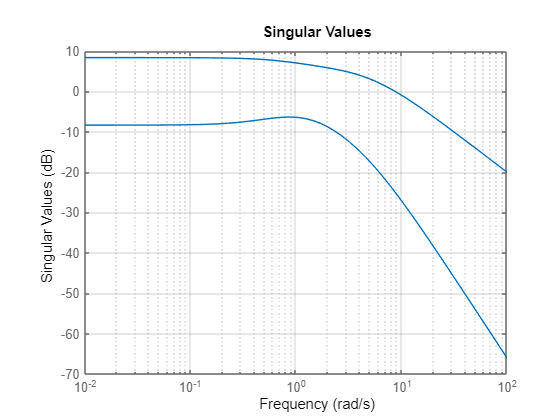

G=1/(0.2*s+1)/(s+1) *[1 1;1+2*s 2];
figure(1)
sigma(G)
grid on

posso anche specificare un range di freq `{freq_min,freq_max}` per cui fare il grafico

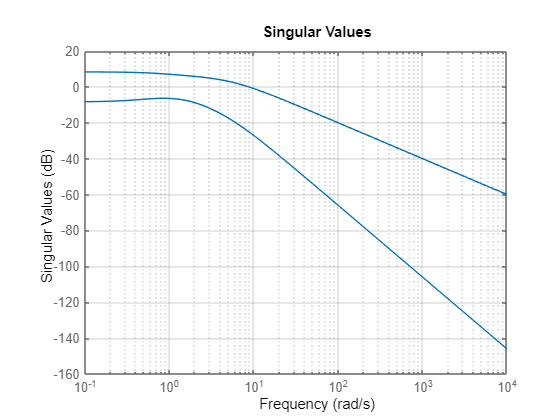

figure(2)
sigma(G,{10^(-1),10^(4)})
grid on

La **norma Hinf** di una mdt è il max ||sigma_max(G)||_2 ovvero il massimo modulo del valore singolare massimo di G (per fdt non serve scomodare i valori singolari ma si considera direttamente la norma 2 della fdt stessa). Tale valore ovviamente può essere dedotto dai grafici dei valori singolari (di sopra) , tuttavia non è sempre preciso. Si usa allora il comando 

norm(G,'inf')

ans = 2.6180

Non sbaglia di sicuro.

Per plottare più grafici `sigma `assieme serve ridefinire anche l'asse delle frequenze

omega=logspace(-1,4,500);

genera `N=500 `punti equispaziati da 10^(`X1=-1) `a 10^(`X2=4)`

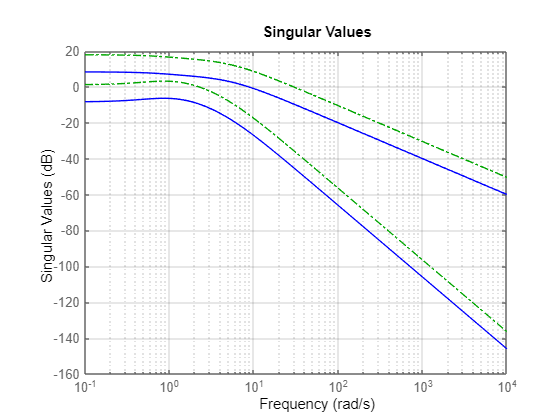

sigma(G,'b-',3*eye(size(G,2))*G,'g-.',omega)
grid on

La **decomposizione ai valori singolari** per una M numerica, NON fdt o mdt!!! si ottiene come

M=[0 2 5;4 95 3;498 20 31];
[U,S,V]=svd(M)

U =    -0.0008   -0.0225   -0.9997
   -0.0166   -0.9996    0.0225
   -0.9999    0.0166    0.0004


S =   499.4309         0         0
         0   94.8076         0
         0         0    4.9295


V =    -0.9971    0.0450    0.0609
   -0.0432   -0.9986    0.0301
   -0.0622   -0.0274   -0.9977


Data una mdt comunque posso ricavarci matrici numeriche **valutando la G** nel numero complesso i*w

freq=300

freq = 300

M=evalfr(G,i*freq)

M =   -0.0001 - 0.0000i  -0.0001 - 0.0000i
   0.0006 - 0.0333i  -0.0001 - 0.0000i


- Gli zeri reali positivi nei MIMO sono infidi (non si vedono bene) e pericolosi come nei SISO, li trovo come

z=tzero(G)

z = 0.5000

Le **direzioni di questi zeri** le trovo come le direzioni per le quali G(z) ha gain nullo--> sono le direzioni di ingresso ed uscita associate al valore singolare nullo che trovo nella svd(G(z))

for i=1:size(z,1)
    zero=z(i)
    G_z=evalfr(G,z(i));
    [U,S,V]=svd(G_z)
    dir_zero_ingresso=V(:,size(V,2))
    dir_zero_uscita=U(:,size(U,2))
end

zero = 0.5000

U =    -0.4472   -0.8944
   -0.8944    0.4472


S =     1.9165         0
         0    0.0000


V =    -0.7071    0.7071
   -0.7071   -0.7071


dir_zero_ingresso =     0.7071
   -0.7071


dir_zero_uscita =    -0.8944
    0.4472


- Per fare una analisi delle performance, ma non solo, sono speso richieste le funzioni di sensibilità e sensibilità complementare. C'è un **comando molto potente** che permette di ricavarle in un attimo, `loopsense` si calcola tutto quello che ci serve:

G =[6/((0.9*s+1)*(0.1*s+1)) -0.05/(0.1*s+1);0.07/(0.3*s+1) 5/((1.8*s-1)*(0.06*s+1))]; %sistema
K=[(7*(s+1))/(0.3*s+1) 0;0 (18*(s+2))/(s+1)]; %controllore

looptransfer=loopsens(G,K);

è tutto pronto, ora basta richiamare quello che ci serve, si fa con `looptransfer.____`

**Sensibilità (e complementare**) viste da ingresso

Si=looptransfer.Si; Si=minreal(zpk(tf(Si)))

Si =
 
  From input "du(1)" to output...
                                              
               (s+3.333)^2 (s+2.048)          
                                              
                       (s+1.111) (s+10)^2     
                                              
                        (s^2 + 15.06s + 809.3)
                                              
   u(1):  -----------------------------------------
                                                   
          (s+10) (s+3.338) (s+2.048)               
                                                   
                  (s+1.001) (s^2 + 14.91s + 762.1) 
                                                   
                    (s^2 + 13.59s + 1686)          
                                                   
 
                                              
               -4.2 (s+16.67) (s+10)^2        
                                              
                       (s+3.333) (s+2)        
                        

Ti=looptransfer.Ti; Ti=minreal(zpk(tf(Ti)))

Ti =
 
  From input "du(1)" to output...
                                                 
             1604.6 (s+3.338) (s+2.048)          
                                                 
                     (s+1) (s^2 + 15.02s + 783.4)
                                                 
                                                 
   uC(1):  -----------------------------------------
                                                    
           (s+3.338) (s+2.048)                      
                                                    
                   (s+1.001) (s^2 + 14.91s + 762.1) 
                                                    
                    (s^2 + 13.59s + 1686)           
                                                    
 
                                              
                4.2 (s+16.67) (s+10)^2        
                                              
                        (s+3.333) (s+2)       
                                             

le equivalenti viste dall'uscita (sono quelle a cui siamo abituati riferirci nel caso SISO):

So=looptransfer.So; So=minreal(zpk(tf(So)))

So =
 
  From input "dy(1)" to output...
                                              
               (s+2.048) (s+3.333)^2          
                                              
                       (s+1.111) (s+10)^2     
                                              
                        (s^2 + 15.06s + 809.3)
                                              
   y(1):  -----------------------------------------
                                                   
          (s+10) (s+3.338) (s+2.048)               
                                                   
                  (s+1.001) (s^2 + 14.91s + 762.1) 
                                                   
                    (s^2 + 13.59s + 1686)          
                                                   
 
                                              
               -5.4444 (s+16.67) (s+10)^2     
                                              
                       (s+1.111) (s+1)^2      
                        

To=looptransfer.To; To=minreal(zpk(tf(To)))

To =
 
  From input "dy(1)" to output...
                                                 
             1604.6 (s+3.338) (s+2.048)          
                                                 
                     (s+1) (s^2 + 15.02s + 783.4)
                                                 
                                                 
   yP(1):  -----------------------------------------
                                                    
           (s+3.338) (s+2.048)                      
                                                    
                   (s+1.001) (s^2 + 14.91s + 762.1) 
                                                    
                    (s^2 + 13.59s + 1686)           
                                                    
 
                                              
                5.4444 (s+16.67) (s+10)^2     
                                              
                        (s+1.111) (s+1)^2     
                                             

analogamente trovo le **funzioni di loop **

Li=looptransfer.Li; Li=minreal(zpk(tf(Li)))

Li =
 
  From input 1 to output...
              1555.6 (s+1)
   1:  --------------------------
       (s+10) (s+3.333) (s+1.111)
 
          4.2 (s+2)
   2:  ---------------
       (s+3.333) (s+1)
 
  From input 2 to output...
        -11.667 (s+1)
   1:  ----------------
       (s+10) (s+3.333)
 
              833.33 (s+2)
   2:  --------------------------
       (s+16.67) (s+1) (s-0.5556)
 
Continuous-time zero/pole/gain model.



Lo=looptransfer.Lo; Lo=minreal(zpk(tf(Lo)))

Lo =
 
  From input 1 to output...
              1555.6 (s+1)
   1:  --------------------------
       (s+10) (s+3.333) (s+1.111)
 
       5.4444 (s+1)
   2:  ------------
       (s+3.333)^2
 
  From input 2 to output...
         -9 (s+2)
   1:  ------------
       (s+10) (s+1)
 
              833.33 (s+2)
   2:  --------------------------
       (s+16.67) (s+1) (s-0.5556)
 
Continuous-time zero/pole/gain model.



!Sono tutti in forma di stato, perciò uso il `tf() `subito dopo

`loopsens` in realtà permette molto di più, ad es:

looptransfer.Poles 

ans =   -6.7954 +40.4975i
  -6.7954 -40.4975i
  -7.4553 +26.5800i
  -7.4553 -26.5800i
 -10.0000 + 0.0000i
  -3.3382 + 0.0000i
  -1.0015 + 0.0000i
  -2.0478 + 0.0000i


        trova i** poli a CL**

looptransfer.Stable

ans = 1

        dà 1 se a CL il** sistema è stabile**, 0 altrimenti

n=looptransfer.Stable;
if n==1
    disp('--Sistema CL è stabile--')
else 
    disp('xx--Sistema CL è instabile--xx')
end

--Sistema CL è stabile--


clear n

- Vediamo come trovare  il **comportamento del sistema CL nel transitorio**:

visto che faremo un plot nel tempo intanto mi definisco una variabile tempo

t_end=1;
time=0:t_end/500:t_end;

il comando `lsim` che useremo è un po "stupidino" e  quindi devo creare un vettore colonna di ingresso con tante righe quanti sono i campioni che vado a valutare

nstep=size(time,2);
ref1(1:nstep)=1; ref2(1:nstep)=0;  %genera vettori riga, sono prima e seconda componente di ingresso
ref=[ref1' ref2'];

così simula la risposta ad un gradino dato sul primo canale, non toccando il secondo. Se voglio dare un gradino su 2^ componente invece, mi basta dare 0 al `ref1 `e 1 su `ref2`

[y,t]=lsim(To(1:2,1:2),ref,time);

simula la risposta del sistema `To(2x2), `avendo dato un ingresso `ref, `per i tempi specificati da `time `

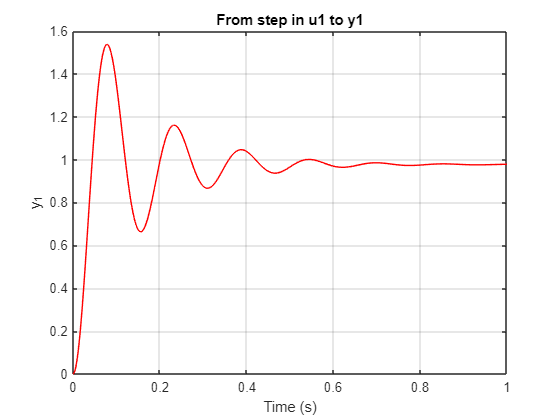

plot(t,y(:,1),'r-') 
grid on 
title('From step in u1 to y1')
xlabel('Time (s)')
ylabel('y_1')

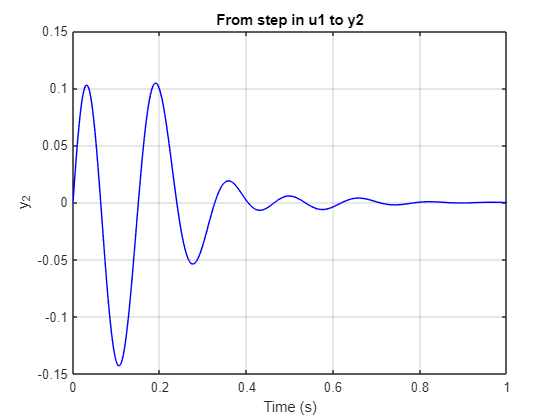

plot(t,y(:,2),'b-') 
grid on 
title('From step in u1 to y2')
xlabel('Time (s)')
ylabel('y_2')

La procedura vista lavora in dominio tempo. 

Esiste una **variante** più breve che lavora nel** dominio della frequenza** (metodo presentato in classe), si basa su `step`

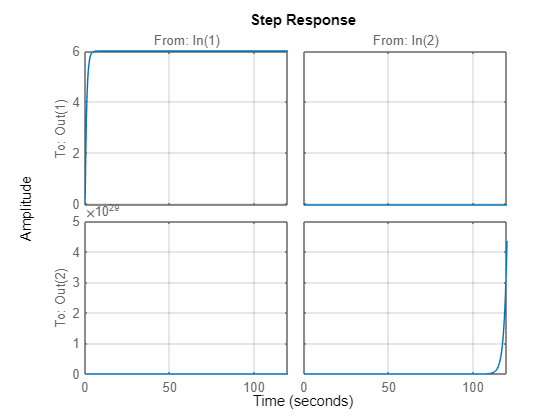

step(G)
grid on

plotta così gli effetti su `G `di un gradino sul canale 1 `[1/s ;0] `o sul canale 2 `[0; 1/s] `

Per dare ingressi su direzioni più specifiche basta andare a definirsi un vettore rappresentativo di tale direzione di controllo

r=[1;1];

e poi calcolare la risposta a gradino

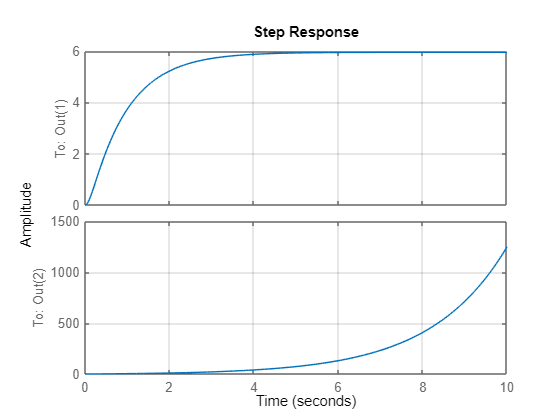

step(G*r)
grid on
xlim([0;10])

- La** forma di Doyle** si ricava con il comando `sysic `, anche lui è problematico e richiede che sia seguita esattamente la notazione qua riportata

G=1/(s+2);
systemnames='G';

            nome del sistema da interconnettere, se ce ne sono di più li devo separare con degli spazi, !         devono già essere stati definiti !

inputvar='[d{1};r{1};n{1};u{1}]';

            definisco gli ingressi esogeni e non, è [w;u] , il {1} indica che sono segnali di dimensione 1

outputvar='[G+d-r;r-G-d-n]';

            variabili d'uscita date come combinazione di `systemname `ed `inputvar `

non dimenticare che va anche detto quale segnale di `inputvar `fa da ingresso a quale `systemname`

input_to_G='[u]';

            !va fatto per ogni sistema dato in `systemname! `

% SysOutName='P'; %a lezione si è dato ma non serve in realtà

            così sa come chiamare il processo generalizzato (blocco superiore della forma di Doyle)

P=sysic

P =
 
  From input "d" to output...
   [+G+d-r]:  1
 
   [+r-G-d-n]:  -1
 
  From input "r" to output...
   [+G+d-r]:  -1
 
   [+r-G-d-n]:  1
 
  From input "n" to output...
   [+G+d-r]:  0
 
   [+r-G-d-n]:  -1
 
  From input "u" to output...
                1
   [+G+d-r]:  -----
              s + 2
 
                 -1
   [+r-G-d-n]:  -----
                s + 2
 
Continuous-time transfer function.



- Passiamo alla **creazione dei controllori otimi H infinito**

Un primo modo è usare `loopsyn `per creare un controllore ottimale stabilizzante `K `tale che la mdt(o fdt che sia) in open loop L=`G`*K sia il più simile possibile alla `Gd `**mdt di loop desiderata**.

Gd=10/s;
G=(10-s)/((1+s)*(1+s+s^2));
K=loopsyn(G,Gd)

K =
 
  A = 
              ?    K.x1    K.x2    K.x3
   ?          0   38.96   217.1  -392.5
   K.x1       0  -20.09  -38.44       0
   K.x2       0   47.22     -41   7.252
   K.x3       0       0   23.97  -400.3
 
  B = 
             u1
   ?      137.9
   K.x1   -34.9
   K.x2  -43.67
   K.x3  -46.63
 
  C = 
           ?   K.x1   K.x2   K.x3
   y1   0.12  339.9   1894  -3423
 
  D = 
         u1
   y1  1203
 
Continuous-time state-space model.



K=minreal(zpk(tf(K)))

K =
 
                                         
  1202.5 (s+511.5) (s+0.01376)           
                                         
                   (s^2 + 4.068s + 12.44)
                                         
  ---------------------------------------
                                      
     s (s+400.8) (s^2 + 60.61s + 2627)
                                      
 
Continuous-time zero/pole/gain model.



La scelta della Gd è un po guidata dalle nostre necessità:

- stabilità robusta--> basso guadagno in AF

- prestazoini--> alto guadagno in BF

- banda influnzata da poli (pi) e zeri (zi) reali positivi di G-->   max|(pi|) <wc< min(|zi|)

- pendeza successiva di -20 o -40db/dec

L'altro metodo è più raffinato e prevede l'**uso di funzioni peso** ed  il comando mixsyn, è il metodo visto a lezione

G=1/(0.2*s+1)/(s+1) *[1 1;1+2*s 2];

Per prima cosa devo definire le funzioni peso:

- `Wp` per la S, serve per avere buon tracking e ridurre l'effetto del disturbo sull'uscita dato che la nostra funzione di Sensitività dovrà sempre stare sotto a 1/Wp. 

                            Ha una forma consigliata            

%Wp= (s/(Mi^(1/n)) +wbi)^n /(s+wbi*Ai^(1/n))^n

dove Mi è il max modulo della Si (S del canale i-esimo), si lega ai margini! ; 

         wbi= frequenza di taglio minima voluta per Si ;

        Ai=max errore a regime accettato nel canale i-esimo

        n=\ 1 se voglio una pendenza maggiore dopo la frequenza di taglio

A1=10^-4; A2=A1;
wb1=0.25; wb2=0.25;
M1=1.5; M2=1.5;
wp1= (s/M1 +wb1) /(s+wb1*A1);
wp2= (s/M2 +wb2) /(s+wb2*A2);
Wp=blkdiag(wp1,wp2)

Wp =
 
  From input 1 to output...
          s + 0.375
   1:  ----------------
       1.5 s + 3.75e-05
 
   2:  0
 
  From input 2 to output...
   1:  0
 
          s + 0.375
   2:  ----------------
       1.5 s + 3.75e-05
 
Continuous-time transfer function.



- `Wu` serve per limitare il modulo del segnale di controllo, di solito è I oppure s/(s+w_taglio_CL) per tenere u anche grande alle BF (non importa come è) ma basso alle AF dove potrebbe portare ad instabilità se troppo alto

Wu=eye(size(G,2))

Wu =      1     0
     0     1


- `Wt` serve per avere una riduzione della sensitività al rumore di misura n, la do come [] se non mi interessa metterla nel problema (vale per qualsiasi peso, lo posso escludere dando al suo posto [])

                        --> è bene che freq_taglio(Wp) < freq_taglio(Wt^-1) sennò non rispetto le prestazioni e robustezza

Wt=[]


Wt =

     []



[Kinf,CL,gamma]=mixsyn(G,Wp,Wu,Wt);
Kinf=minreal(zpk(Kinf)) %come al solito Matlab mi fornisce K in ss altrimenti

Kinf =
 
  From input 1 to output...
                                                
       17.782 (s+1) (s+5) (s^2 + 7.287s + 17.66)
                                                
                                                
   1:  -----------------------------------------
                                             
          (s+2.5e-05) (s^2 + 6.778s + 13.01) 
                                             
                      (s^2 + 22.84s + 249.5) 
                                             
 
                                         
       -25.194 (s+9.216) (s+5)           
                                         
                         (s+1) (s+0.6318)
                                         
   2:  -----------------------------------
                                          
       (s+2.5e-05) (s^2 + 6.778s + 13.01) 
                                          
                   (s^2 + 22.84s + 249.5) 
                                          
 
  From input 2 t

Ricava il controllo ottimo `Kinf` per minimizzare la norma H infinito di N=[`Wp`*S; `Wu`*K*S; `Wt`*T].

Tiene dunque S,KS,T (i loro valori singolari max, nel caso MIMO) <= `gamma*Wp,Wu,Wt `(gamma*sv_minimo delle funzioni peso, nel caso MIMO). 

--> `gamma `mi dice quanto sono riuscito a rispettare le specifiche (deve essere minore di 1 sennò ho fallito)

gamma

gamma = 2.8020

`CL `invece è la forma di stato risultante della mixed sensitivity N.

Matlab fornisce anche una **funzione per creare delle funzioni peso** in forma di stato con certe caratteristiche date (il template creato è diverso da quello usato noi):

%W=makeweight(dcgain,[freq,mag],hfgain,Ts,N)

- dcgain=W(0) in numeri assoluti, guadagno statico

- pongo un punto di passaggio per [freq,mag] --> uso [wt,1] o solo wt per dare la freq di taglio di W

- hfgain=W(inf) in numeri assoluti--> =0 se il modulo AF è -inf dB

- Ts=0 se W è TC

- N=1 di default, è l'ordine di W

#### Introduzione alle incertezze

- Iniziamo ora a considerare la presenza di parametri incerti, negli es si farà riferimento ad un sistema massa-molla-smorzatore.

Il comando più semplice per descrivere l'incertezza parametrica è `ureal('Name',NominalValue,'Property',Value)`

m=ureal('m',3,'PlusMinus',[-1.2,1.2])
c=ureal('c',1,'Range',[0.8,1.2])
k=ureal('k',2,'Percentage',[-40,40])

`        'Name'= `Nome del parametro

`        'NominalValue'= `valore nominale che scelgo per il parametro

`        'Property'= `in che modo indico la deviazione dal valore nominale:

- deviazione assoluta con `'PlusMinus'`

- range di valori [min,max] con `'Range'`

- variazione percentuale con `'Percentage'`

`        'Value'= `valore dell' incertezza data secondo `'Property'`

Una volta descritto il sistema con

A=[0 1;-k/m -c/m]; 

m =   Uncertain real parameter "m" with nominal value 3 and variability [-1.2,1.2].


B=[0;1/m];

c =   Uncertain real parameter "c" with nominal value 1 and range [0.8,1.2].


C=[1 0]; D=0;

k =   Uncertain real parameter "k" with nominal value 2 and variability [-40,40]%.


usys=ss(A,B,C,D);

con matrici contenenti parametri incerti, posso provare a semplificare il modello riducendo il numero di occorrenze dei parametri con

simplify(usys,'full')

Nota che il risultato è di classe `uss, `come il risultato ottenuto con un qualsiasi altro metodo:

- `tf([coeff num],[coeff den])`

- `feedback(loop,retroaz)`

- costruzione diretta di G

Potrei voler ricalcolare un elemento incerto (es. una matrice A) per un determinato valore:

% A_new=usubs(A,'name1',value1,'name2',value2...)
 A_new=usubs(A,'m',3.8,'k',1.6,'c',1)

        impone che gli elementi incerti `name1,name2,... `contenuti in A abbiano i valori         `value1,value2,...`

Come `value `è accettato anche:

- `'NominalValue' `per settare name al valore nominale specificato nella sua definizione in `ureal`

- `'Random' `per dare a `name `un valore casuale tra quelli per lui ammissibili

 A_new=usubs(A,'m','NominalValue','k',1.6,'c','Random')

Per campionare A in maniera casuale per n volte uso il comando

 n=50;

ans =

  Uncertain continuous-time state-space model with 1 outputs, 1 inputs, 2 states.
  The model uncertainty consists of the following blocks:
    c: Uncertain real, nominal = 1, range = [0.8,1.2], 1 occurrences
    k: Uncertain real, nominal = 2, variability = [-40,40]%, 1 occurrences
    m: Uncertain real, nominal = 3, variability = [-1.2,1.2], 3 occurrences

Type "ans.NominalValue" to see the nominal value, "get(ans)" to see all properties, and "ans.Uncertainty" to interact with the uncertain elements.



 usample(A,n);

salva i risultati come [A1 |`A2 ...|An]`

 Gp_no=tf(usys); % tf è stronzo e se ci dai un modello incerto questo infame se lo calcala per un set specifico di parametri

A_new =          0    1.0000
   -0.4211   -0.2632


 bode(usys); grid on  %in compenso bode &co. sono più bravi e accettano direttamente le forme di stato incerte)

dare il comando `bode `per una Gp con elementi incerti (se definita direttamente con la sua espressione e non con tf), crea 20 (numero di default) diagrammi di Bode di Gp calcolata per valori random (più il nominale) dei parameri contenuti.

Stessa cosa fa per le funzioni `impulse,bodemag,nyquist,step (tutte loro possono essere usate dandoci elementi uss per ottenere il risultato mostrato)`

Abbiamo già visto come per valutare una fdt per una frequenza specifica si usi il comando `evalfr. `Per fare grafici come bode, plot o nyquist( per lui essendo sul piano C basta anche `evalfr)` è invece più comodo usare `frd:`

 w=logspace(-1,3,100);

A_new =          0    1.0000
   -0.5333   -0.3753


sample=frd(Gp,w);

        crea dei campioni della Gp per tutte le frequenze definite in w; li salva come tabella (coppia di punti (freq,mag) ) così da tenere accoppiato il valore di Gp(jw) con la w a cui lo calcolo.

        è simile a `evalfr `dove però mi viene dato solo il valore di G(jw) ma non tiene traccia della w a cui è calcolata

        Per i Bode èdecisamente più comodo `frd`

Per analizzare il comportamento del sistema per valori uniformente distribuiti dei parametri, similmente a `usample, `ma con un campionamento uniforme nel range ammissibile, uso `gridureal(A,n).`

Se in A ho più parametri incerti, posso usare la notazione estesa `[A_new,SampleValues]=gridureal(A,'name1',n1, 'name2',n2,...)`

così da prendere n1 campioni di name1 , n2 di name2 e così via.

[A_new,SampleValues]=gridureal(A,'m',30, 'k',26,'c',52);

`gridureal e usample `servono per es. per graficare `step,bode,... `per più dei 20 campioni di default (!campiona il sistema incerto-->gli devo passare un `uss`)

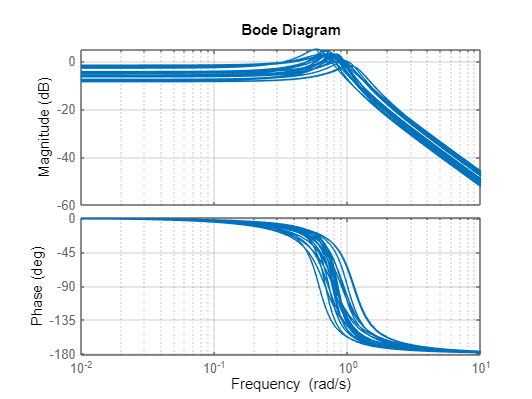

step(gridureal(usys,50))
title('campionamento uniforme di usys')
step(usample(usys,50)) %specificando solo un valore di campioni, considera
%di prendere 50 set di parametri incerti
title('capionamento random di usys')

"Uncertain State Space" è il blocco Simulinkusato per simulare e linearizzare dei sistemi incerti.

Esiste anche un comando per poter ottenere la forma di Doyle con incertezza, ovvero la Gnom con chiusura del loop in alto tramite il blocco$\Delta \;$ . Il comando è `lftdata `

[Gnom,Delta,Blkstruct,Normunc]=lftdata(usys)

        Dando un sistema incerto `sys `mi fornisce:

-  `Gnom= `Sistema nominale in forma ss (blocco inferiore della struttura)

- `Delta`= Matrice $\Delta$ con $||\Delta ||{\;}_{\infty } \le 1$ (blocco superiore della struttura)

- `Blkstruct`= matrice nx1, il suo i-esimo elemento mi da l'i-esimo elemento normalizzato dell'incertezza

- `Normunc `vettore di elementi incerti

Nei titoli o come variabile `char `per scrivere  $\omega \;$si fa come per Word o LaTeX con \omega .

Ultimo elemento di `legend `è un numero da 1 a 4 e corrisponde a dove mettere la legenda (numera gli angoli del grafico con 1 in alto a sinistra e gli altri disposti in senso orario).

#### Modelli con incertezza additiva

(usiamo come riferimento la fdt  $\frac{k}{\tau s+1}$ )

- Per scegliere il peso $w_A \left(s\right)$ devo usare una fdt con modulo sempre sopra all'errore assoluto $|G_p \left(s\right)-G_{\textrm{nom}} \left(s\right)|$ . La scelta procede dunque con due step:

- Graficare l'errore assoluto 

w=logspace(-1,3,100);
s=tf('s');
G_nom= 2.5/(2.5*s+1);
for k=2:0.1:3
    for tau=2:0.1:3
        G_p=k/(tau*s+1);
        abs_error=frd(G_p,w)-frd(G_nom,w);  %calcolo l'errore assoluto punto per punto
        bodemag(abs_error,w,'k--'); grid on
        hold on
    end
end
hold off  %solo perchè dopo è presentato un caso alternativo

!! Devo dare un ciclo `for `per ogni parametro così da far spaziare i campioni nel loro range (ordine con cui li metto non è importante) !!

        1.1.Metodo alternativo per graficare gli errori senza la necessità di usare dei cilcli for (metodo presentato dal prof):

Al posto dei cicli `for `vado a definire i parametri incerti con `ureal`

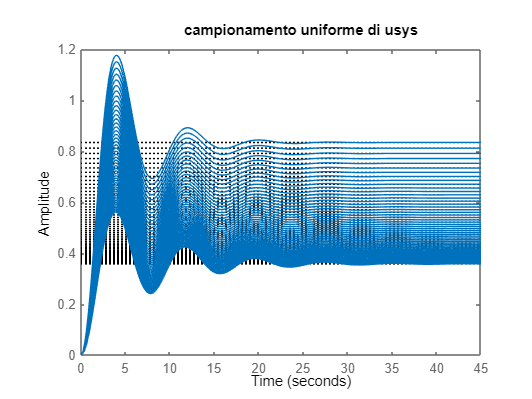

k=ureal('k',1,'Range',[0.8,1.2]);

T=ureal('T',1/15,'Range',[0.7/15 1.3/15]);

ovviamente serve comunque creare la Gp

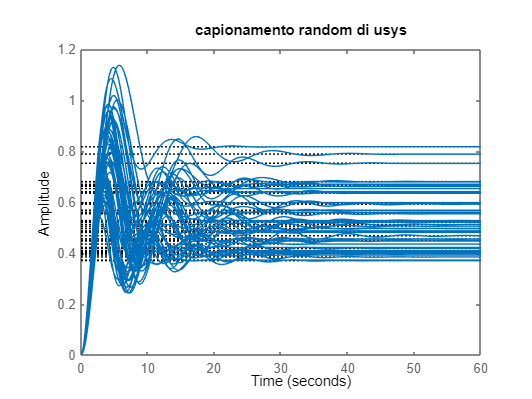

s=tf('s');

Gp=k/(T*s+1);

Vado subito a graficare l'errore, tanto la G nominale posso estrarla da Gp con la funzione `.NominalValue `-->non serve definirla separatamente

bodemag(usample(Gp-Gp.NominalValue, 100),'k--'); grid on

Gnom =
 
  A = 
            x1       x2
   x1        0        1
   x2  -0.6667  -0.3333
 
  B = 
            u1       u2       u3       u4
   x1        0        0        0        0
   x2  -0.4472  -0.8944   0.7303   0.3651
 
            u5       u6
   x1        0        0
   x2  -0.3651   0.3333
 
  C = 
           x1      x2
   y1       0  0.1491
   y2  0.2981       0
   y3  0.3651       0
   y4       0  0.3651
   y5       0       0
   y6       1       0
 
  D = 
            u1       u2       u3       u4
   y1        0        0        0  -0.1633
   y2        0        0  -0.3266        0
   y3        0        0     -0.4        0
   y4        0        0        0     -0.4
   y5        0        0        0        0
   y6        0        0        0        0
 
            u5       u6
   y1        0        0
   y2        0        0
   y3        0        0
   y4        0        0
   y5     -0.4   0.3651
   y6        0        0
 
Continuous-time state-space model.


Delta =

  Uncertain matrix 

Blkstruct = 3×1 struct array with fields:
    Name
    Size
    Type
    Occurrences
    Simplify


Normunc = 5×1 cell array
    {1×1 ureal}
    {1×1 ureal}
    {1×1 ureal}
    {1×1 ureal}
    {1×1 ureal}


        2. Trovare la curva limite superiore (Upper Bound) (nella nostra notazione corrisponde a $w_A \left(j\omega \right)$ per il caso additivo e $w_I \left(j\omega \;\right)$ per il moltiplicativo )

[freq,resp_db]=ginput(5); %serve per campionare il grafico attivo--> riapre il grafico attivo, col muose devi andare a selezionare i 5 punti per cui la W dovrà passare (ricorda che è un upper bound da creare)
resp=10.^(resp_db/20);  %converte la risposta da dB in nuero puro
sys=frd(resp,freq);  %si genera un sistema in frequenza (unfrd) che passa per i punti campionati alle corrispondenti frequenze
ord=2; %scelgo l'ordine dell'upper bound
Wa=fitmagfrd(sys,ord);  %crea la curva che sta sempre sopra al Bode del sys dato
Wa=tf(Wa) %riporto il risultato come fdt
hold on
bode(Wa)
hold off

In realtà la funzione `fitmagfrd, `che mi consente di trovare la funzione peso, ammette un ulteriore ingresso `RD. RD `di default è settato a 0 ed indica il grado relativo voluto per W. Un eccesso poli-zeri diverso da 0 permette a W di non andare piatta in AF ma scendere con $-20\cdot \mathrm{RD}\;\frac{\mathrm{dB}}{\mathrm{dec}}$ -->non resto troppo sopra ai grafici alle AF

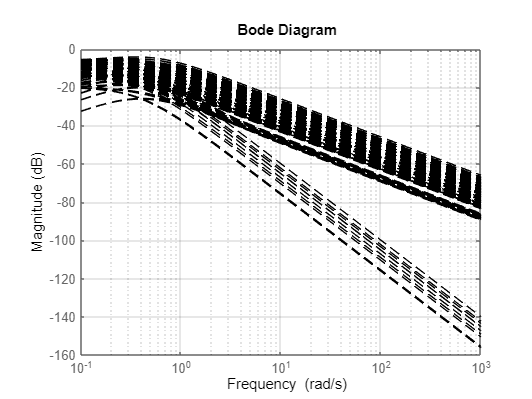

%dovrei dare W=fitmagfrd(sys,ord,RD) , la cosa è già implementata nella mia
%upperbound quindi per  l'es uso lei

%Wa_a=upperbound(Gp-Gp.NominalValue,5,0)
%Wa_b=upperbound(Gp-Gp.NominalValue,5,1)

#### Modello con incertezza moltiplicativa

Comandi per disegnare i Bode degli errori relativi $\frac{|G_p \left(s\right)-G_{\textrm{nom}} \left(s\right)|}{|G_{\textrm{nom}} \left(s\right)|}$ sono identici al caso di incertezza additiva. Ovviamente anzichè l' `abs_error `dovrò definire e poi graficare un `rel_error `

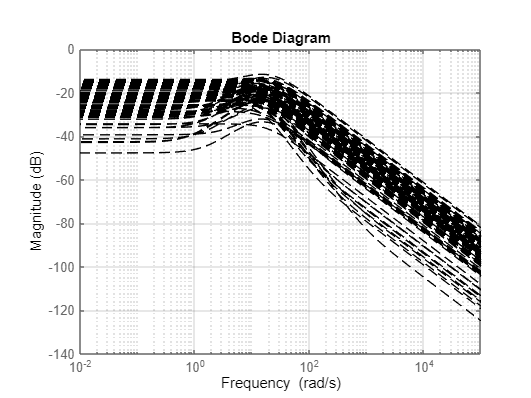

w=logspace(-1,3,100);
s=tf('s');
G_nom= 2.5/(2.5*s+1);
for k=2:0.1:3
    for tau=2:0.1:3
        G_p=k/(tau*s+1);
        rel_error=(frd(G_p,w)-frd(G_nom,w))/frd(G_nom,w);  

        bodemag(rel_error,w,'k--'); grid on
        hold on
    end
end

[freq,resp_db]=ginput(5); 
for i=1:5
    resp(i)=10^(resp_db(i)/20); 
end

Wa =
 
  0.01145 s^2 + 0.4731 s + 2.922
  ------------------------------
      s^2 + 2.491 s + 3.281
 
Continuous-time transfer function.



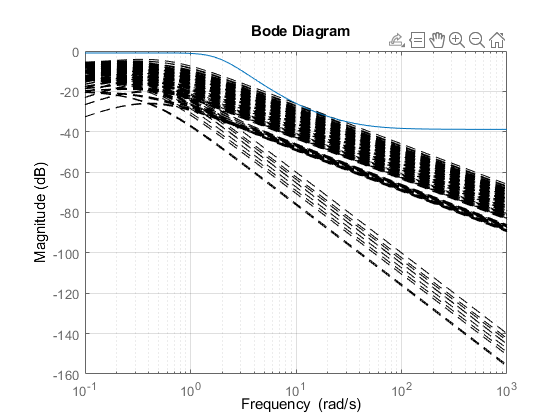

sys=frd(resp,freq);  
ord=2;
Wi=fitmagfrd(sys,ord); 

Wi=tf(Wi)
hold on
bode(Wi)
hold off

#### Dinamiche non modellate

Consideriamo gli impianti  $G_p \left(s\right)=G_{\textrm{nom}} \left(s\right)f\left(s\right)$ dove f(s) è il termine che voglio trascurare (può essere incerto o no).  

Scrivo l'incertezza moltiplicativa come $G_p \left(s\right)=G_{\textrm{nom}} \left(s\right)\left(1+w_I \left(s\right)\Delta_I \left(s\right)\right)\;$ con $|\Delta_I \left(j\omega \right)|<1\;\forall \omega$  

allora $\frac{G_p \left(s\right)-G_{\textrm{nom}} \left(s\right)}{G_{\textrm{nom}} \left(s\right)}=f\left(s\right)-1$ $\;\;\Rightarrow l_I \left(s\right)=\max_{G_p } \left\lbrace \frac{|G_p \left(s\right)-G_{\textrm{nom}} \left(s\right)|}{|G_{\textrm{nom}} \left(s\right)|}\right\rbrace \equiv \underset{f\left(s\right)}{\max \left\lbrace |f\left(s\right)-1|\right\rbrace }$

Posso riusare i comandi visti nel caso di incertezza additiva dove al posto di `abs_error `userò `pert=frd(f(s)-1,w) --> `grafico l'errore relativo dando la dinamica da trascurare.

I comandi per trovare la upper bound possono essere compattati in una funzione` upperbound`

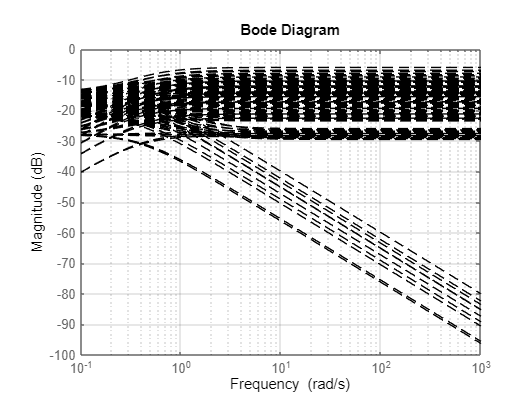

%% Funzione per trovare l'upper bound di un insieme di diagrammi di Bode
% function [W]=upperbound(fun_trasf,ordine,numero_di_punti,ord_rel)
%     G=fun_trasf;
%     ord=ordine;
%     n=numero_di_punti;
%     ord_rel=[];
%     if  isempty(ord_rel)==1
%         RD=0;
%     else
%         RD=ord_rel;
%     end
%     figure;
%     bode(G);
% 
%     
%     
%     [freq,resp_db]=ginput(n); 

%     %for i=1:n
%         %resp(i)=10^(resp_db(i)/20); 
%     %end
%     resp=10.^(resp_db/20);
%     sys=frd(resp,freq);  
%     W=fitmagfrd(sys,ord,RD); 
%     W=tf(W)
%     hold on
%     bode(W);

Wi =
 
  0.7117 s^2 + 1.918 s + 1.667
  ----------------------------
      s^2 + 2.259 s + 3.1
 
Continuous-time transfer function.



%     hold off
% end

e quindi basta salvare la funzione nello stessa cartella dello script in cui la si usa per farla funzionare.

- Tracciare le regioni esatte di incertezza su Nyquist (non le circonferenze approssimanti)

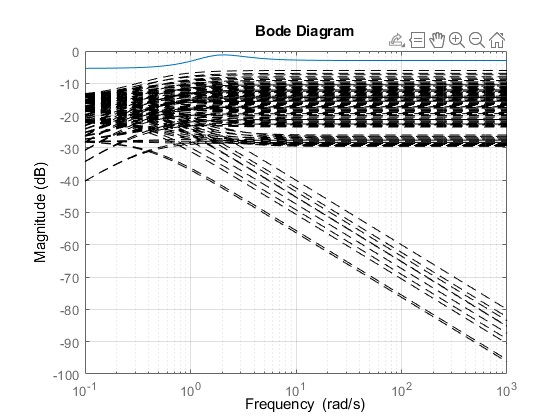

s=tf('s');

Gp0=2.5/(2.5*s+1);
nyquist(Gp0,'b');hold on
title('Regioni d''incertezza');
for k=2:0.1:3
    for tau=2:0.1:3
        Gp=k/(tau*s+1);
        sample=evalfr(Gp,1i);
        plot(sample,'k*');  %plotta la Gp calcolata per tanti set di valori di k,tau a w=1
    end
end
plot(evalfr(Gp0,1i),'b*') %serve solo se voglio vedere anche il valore corrispondente al caso nominale

- Potrei anche voler inserire un parametro incerto complesso, in maniera simile a `ureal `si usa

Bc=ucomplex('Bc',6-i,'Percentage',25)

adesso basta un solo limite in `Value `perchè è riferito al modulo del numero complesso--> non acctta sue riduzioni. (se Bc è matriciale, usa `ucomplexm`)

sa=squeeze(usample(Bc,40));

serve darci `squeeze `perchè usample sui complessi da elementi a 3 dim (Re,Im,1) --> squeeze toglie l'1 inutile.

plot(sa,'o'); axis equal

- Il blocco di incertezze $\Delta$ posso trovarlo non solo come risultato di `lftdata `ma lo posso anche andare a costruire come 

%Delta=ultidyn('Name',[#ingressi, #uscite])
Delta=ultdyn('Delta',[1,1])

lo uso per definire modelli con incertezza non strutturata.

Così tutti i possibili impianti li posso definire come

%Gp=G*(1+wi*Delta)

coi Wi trovati dalla funzione di upperbound.

Andiamo a vedere come potere calcolare i margini di robustezza per un usys

Definiamo intanto il problema:

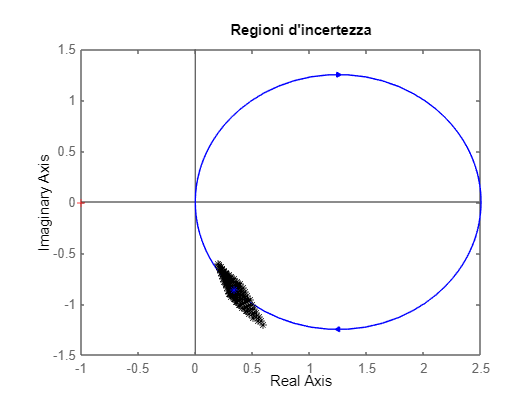

s=tf('s');

G=3*(-2*s+1)/(5*s+1)/(10*s+1);
wi=(10*s+0.33)/(1+(10/5.25)*s);
Delta=ultidyn('Delta',[1,1]);

Bc =   Uncertain complex parameter "Bc" with nominal value 6-1i and variability 25%.


Gp=G*(1+wi*Delta);
K=tf([12.7,1],[12.7,0]);
T=feedback(Gp*K*1.13,1);

Il comando per vedere i margini di robusta stabilità è 

robstab(T)

        `STABMARG=`margini

        `WCU=`minima perturbazione che causa instabilità